clc,clear,close all
global Center
global Element
global hstep

设置方程

u0 = @(x) sin(-pi*x);   % 初值
left = 0;              % 求解区间
right = 2;              % 求解区间
time = 0.1;          % 时间
num = 5;               % 区间数量

分配内存

Num = num+2;                        % 周期边界条件，左右各加一个区间后，区间数量
% delta_t = 0.1*(right-left)/num;     % 时间步长
delta_t = 0.001;
hstep = (right-left)/num;           % 每个区间的长度，这里设置成等长。
Element_l = left-hstep:hstep:right; % 每个区间的左边界，大小为 1xNum
Element_r = left:hstep:right+hstep; % 每个区间的右边界，大小为 1xNum
Element = [Element_l',Element_r'];  % 每个区间的左右边界，大小为 Numx2
Center = mean(Element,2);           % 每个区间的中心点，大小为 Numx1

初始化

U = Uinitial(u0,num);

龙格库塔迭代

[U,Upm,m_Hflux] = SolveStep(U);
now = 0;
while now<time
    if now+delta_t>time
        delta_t = time-now;
    end
    U = RungeKutta(U,delta_t);
    now = now+delta_t;
    now
end

now = 1.0000e-03

now = 0.0020

now = 0.0030

now = 0.0040

now = 0.0050

now = 0.0060

now = 0.0070

now = 0.0080

now = 0.0090

now = 0.0100

now = 0.0110

now = 0.0120

now = 0.0130

now = 0.0140

now = 0.0150

now = 0.0160

now = 0.0170

now = 0.0180

now = 0.0190

now = 0.0200

now = 0.0210

now = 0.0220

now = 0.0230

now = 0.0240

now = 0.0250

now = 0.0260

now = 0.0270

now = 0.0280

now = 0.0290

now = 0.0300

now = 0.0310

now = 0.0320

now = 0.0330

now = 0.0340

now = 0.0350

now = 0.0360

now = 0.0370

now = 0.0380

now = 0.0390

now = 0.0400

now = 0.0410

now = 0.0420

now = 0.0430

now = 0.0440

now = 0.0450

now = 0.0460

now = 0.0470

now = 0.0480

now = 0.0490

now = 0.0500

now = 0.0510

now = 0.0520

now = 0.0530

now = 0.0540

now = 0.0550

now = 0.0560

now = 0.0570

now = 0.0580

now = 0.0590

now = 0.0600

now = 0.0610

now = 0.0620

now = 0.0630

now = 0.0640

now = 0.0650

now = 0.0660

now = 0.0670

now = 0.0680

now = 0.0690

now = 0.0700

now = 0.0710

now = 0.0720

now = 0.0730

now = 0.0740

now = 0.0750

now = 0.0760

now = 0.0770

now = 0.0780

now = 0.0790

now = 0.0800

now = 0.0810

now = 0.0820

now = 0.0830

now = 0.0840

now = 0.0850

now = 0.0860

now = 0.0870

now = 0.0880

now = 0.0890

now = 0.0900

now = 0.0910

now = 0.0920

now = 0.0930

now = 0.0940

now = 0.0950

now = 0.0960

now = 0.0970

now = 0.0980

now = 0.0990

now = 0.1000

U

U =     0.6715   -0.0847   -0.0059
   -0.6715   -0.0847    0.0059
   -0.8031    0.0456    0.0026
   -0.0000    0.0773    0.0000
    0.8031    0.0456   -0.0026
    0.6715   -0.0847   -0.0059
   -0.6715   -0.0847    0.0059


计算在Center点的数值解和解析解

xx = linspace(left,right,num+1);


syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy1(i) = u(U,i,x);
    yy2(i) = double(u0(xii));
end


计算误差

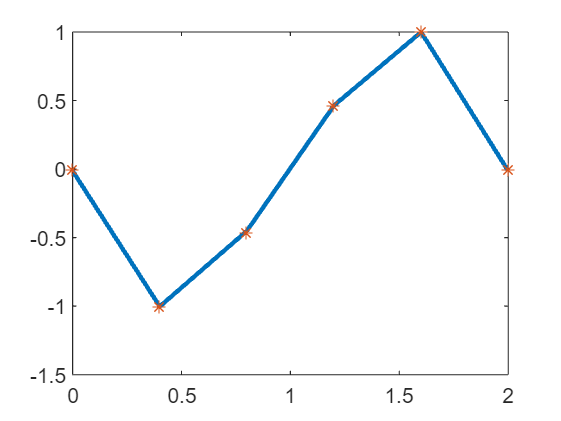

err1 = abs(yy1-yy2);
plot(xx,yy1,'LineWidth',2)
hold on
plot(xx,yy2,'*')

num

num = 5

disp(norm(err1,inf))

    0.0134

